# **罗列纳米棒计算结果**

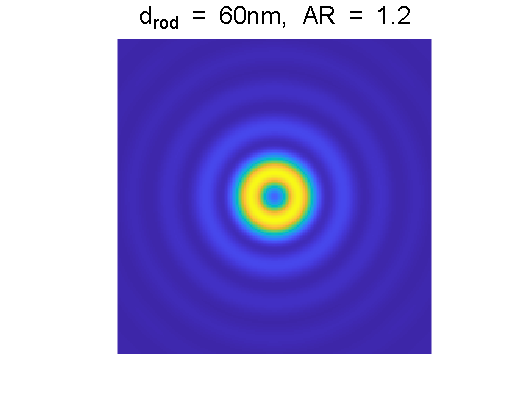

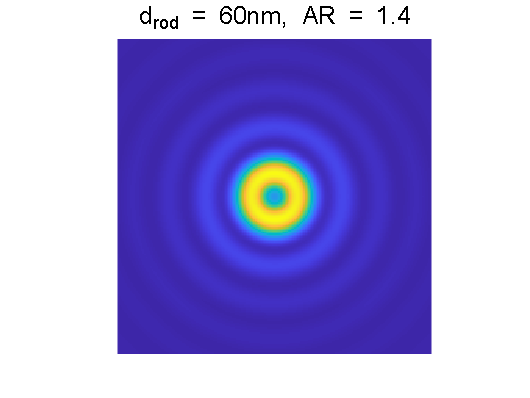

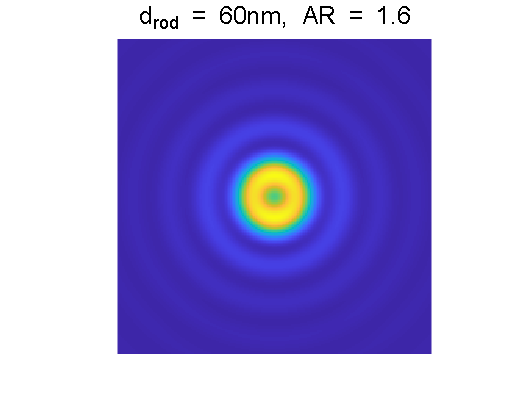

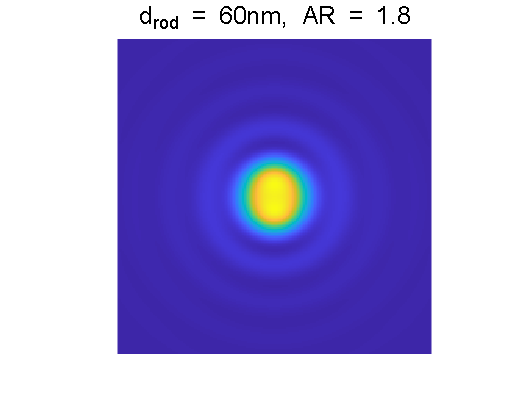

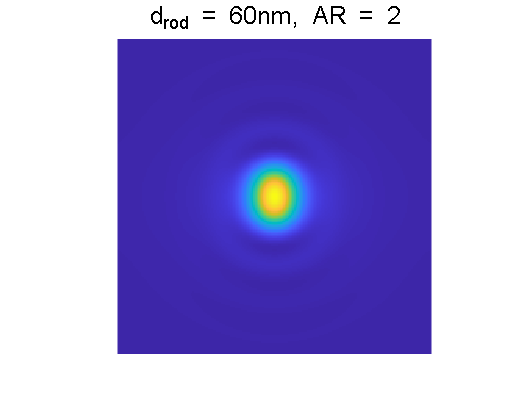

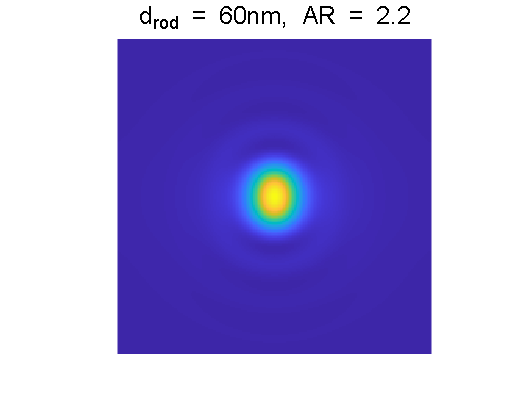

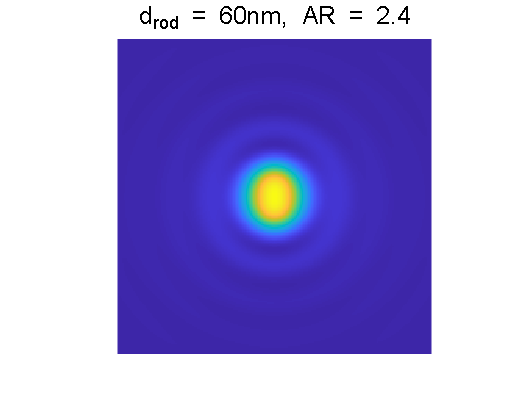

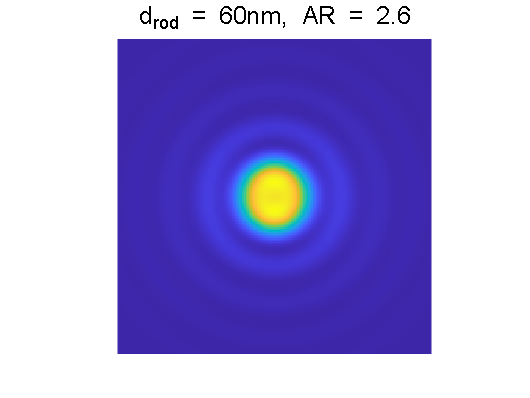

filedir = 'E:\work\SPR-DF\模拟\MNPBEM\nanorod_2_AR_1-2_0-2_4';
files = dir(fullfile(filedir, '*.mat'));
load(fullfile(filedir, files.name));
AR = 1.2:0.2:4;
for ii = 1:length(AR)
    d_rod = p_rod.result.param.d;
    f = figure;
    imagesc(squeeze(sum(I(:, :, :, ii), 3))); axis equal; axis off;
    title(['d_{rod} = ', num2str(d_rod) 'nm, AR = ' num2str(AR(ii))], 'fontsize', 15);
    figpath = fullfile(filedir, ...
        ['d_rod = ', num2str(d_rod) 'nm, AR = ' num2str(AR(ii))]);
    saveMyfig(f, figpath);
end